# **IO672 - MIL-STD-1553 Loopback**

This example shows you how to perform a loopback test with the IO672 MIL-STD-1553 I/O module, to verify the basic protocol communication over the transmit and receive channels.

The IO672 single-function version supports either bus controller, 31 remote terminals or bus monitor operation. The multi-function version can operate in all three modes simultaneously.

The Simulink model features the [IO672 MIL-STD-1553 - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_setup), [IO672 - Initialize](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_initialize), [IO672 - Bus Controller Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_bus_controller_send), [IO672 - Create BC Message List](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_create_bc_message_list), [IO672 - Encode BC Message](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_encode_bc_message), [IO672 - Decode BC Message](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_decode_bc_message), [IO672 - RT Initialize](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_rt_initialize), [IO672 - RT Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_rt_send) and [IO672 - RT Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_rt_receive) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO672-2-MF I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Test Setup

In this example, data is sent from the bus controller on channel 1 to the remote terminal on channel 2. You must therefore connect the pins on the terminal board where the MIL-STD-1553 channels are located.

Other variants of the IO672 can be used as well for this example. At least a 1-channel multi-function or a 2-channel single-function module is required. 

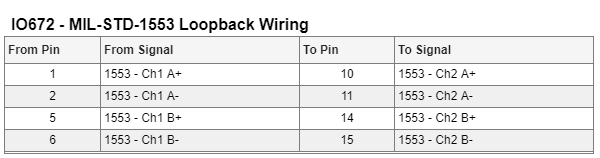

The complete pin mapping of the IO672 can be found here: [IO672 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO672_MILSTD1553Loopback';
open_system(modelName);

### Model Description

In the model, a sine wave signal is encoded by the [IO672 Encode BC Message](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_encode_bc_message) block into a MIL-STD-1553 message and transmitted to the remote terminal by the bus controller on channel 1. As the encode block expects an array of uint16 elements, the sine signal must be packed with the [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) block*.* To receive the response from the remote terminal, a second message must be allocated by the [IO672 Create BC Message List](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_create_bc_message_list) block before this message is fed to the [IO672 Bus Controller Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_bus_controller_send) block. After transmitting the message, this block awaits the response from the remote terminal. The response message is decoded by the [IO672 Decode BC Message](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_decode_bc_message) that provides the raw data. This data must be unpacked with the [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block to retrieve the original signal. 

On the side of the Remote Terminal, the message from the Bus Controller is multiplied by 3 and sent back on channel 2 by the [IO672 RT Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_rt_send) block. The signal received is converted to a double value with a [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block. This allows for better manipulation of the signal. To return the signal, the signal is converted back to an uint16 value, as this is the expected datatype of the [IO672 RT Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_rt_send) block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the first Simulink scope connected to the [IO672 Bus Controller Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io672_bus_controller_send) block of channel 1. The second scope connected to the Remote Terminal of channel 2 is used to verify if the data has been successfully processed in the Remote Terminal. In the first scope, a sine wave signal must be displayed, and the exact same signal must also be visible in the second scope:

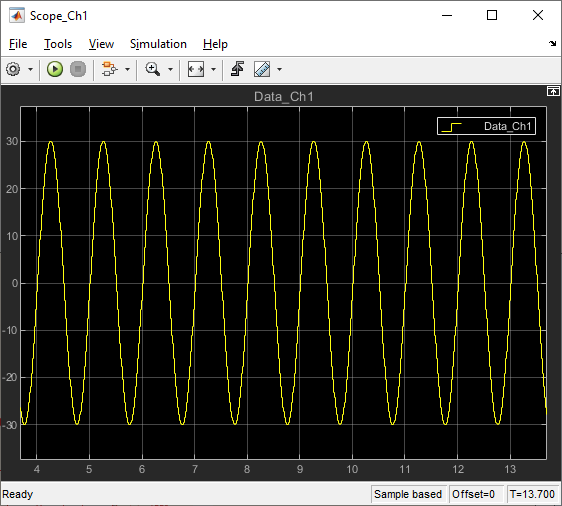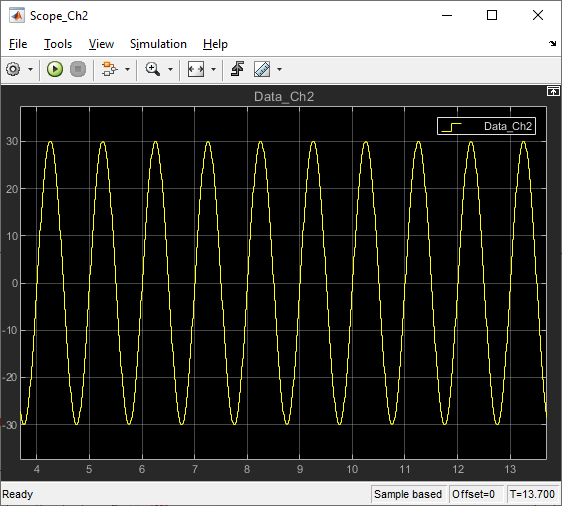

## Additional References

- [IO672 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io672)